# **ADT Localization**

***(Autonomous Vehicle Localization Using Onboard Sensors and HD-Geolocated Maps [MATLAB Project #20] - Spring 2024 Semester)***

[***Project Link***](https://github.com/mathworks/MATLAB-Simulink-Challenge-Project-Hub/tree/main/projects/Autonomous%20Vehicle%20Localization%20Using%20Onboard%20Sensors%20and%20HD%20Geolocated%20Maps)*** - ***[***Our Submission***](https://github.com/Hazem-M-Abdelaziz/Autonomous-Vehicle-Localization-Using-Onboars-Sensor-and-HD-Geolocated-Maps-Project-Solution)

**Presented by: **

- Hazem Mohsen Abdelaziz 

- Yousra Adly Deifallah

**Under Supervision of:**

-   Prof. Mohamed Ibrahim Awad (Head of Mechatronics department - Faculty of Engineering - Ain Shams University) 

## **Load Data, Run Model & Prepare Camera Frames**

Firstly, you must be in the directory of the ADT_Localization Folder. 

This Section will Open the ADT Localization Simulink Model, load pose (X, Y, Yaw) data required for the Vehicle, set the parameters of Camera, Lidar, GPS, IMU, INS sensors and the Scene sampling time. Afterthat, it will run the model to get the sensors output in the workspace (Results). Finally, it will convert video to frames and get some parameters to be used later on in the code. 

***If you want to use another map with another ground truth, make your ground truth in .mat file format with and X position data in 1st column, Y position data in 2nd column, Yaw orientation data in 3rd column and sampling time in 4th column then change its name in the variablesInitialization.m file. ***

***In simulink model, change map name in the Simulation 3D Scene Configuration block in the simulink model. Change the GPS velocities, too.***

***Finally, in maps visualizing, change the map name in the code according to the map you used.***

%Open Simukink Model for data analysis and Loccalization 
open_system('C:\Users\bdrm4\OneDrive\Documents\GPP\ADT_Localization\ADT_SimulinkModel.slx'); %Add the path of the ADTSimulinkModel

%Load setpoints for scene components and set the sensors Parameters 
variablesInitialization; 

%Run Simulink Model and Extract output
Results = sim('ADT_SimulinkModel');

%Convert video to frames 
convertVideoToFrames; %warning if the images folders exists 

Frames are stored in the folder


## **Visualize Ground Truth Pose of the Vehicle on US City Block Map**

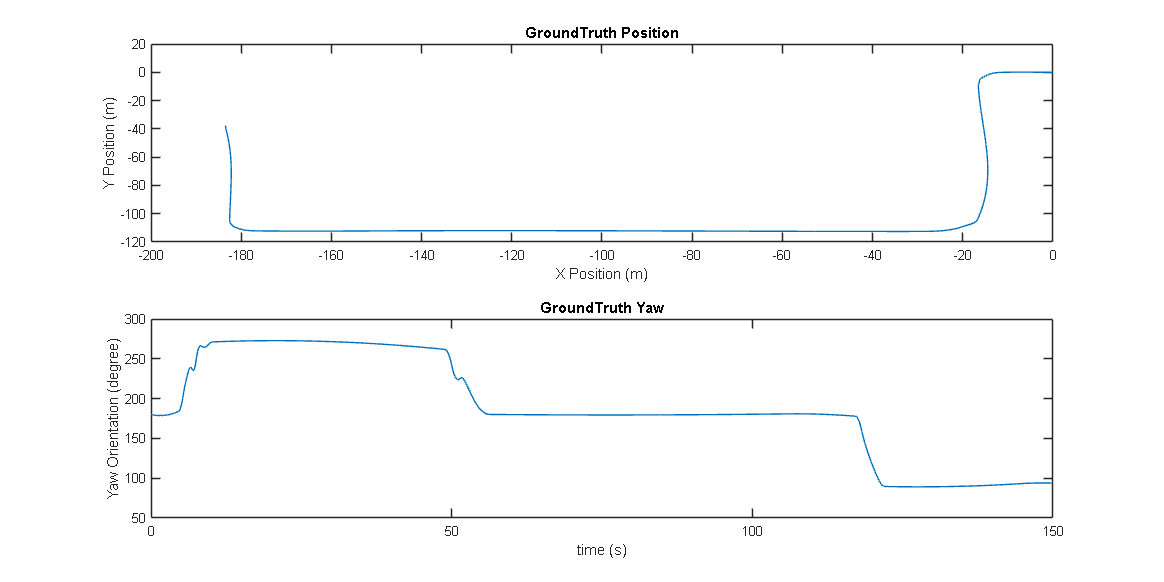

%Visualize groundtruth Position and Orientation data.
figure;
figure('Position', [50, 50, 2000, 1000]); % [left bottom width height]

%Creating subplots
subplot(2, 1, 1);
plot(refX, refY);
xlabel('X Position (m)');
ylabel('Y Position (m)');
title('GroundTruth Position');
 
subplot(2, 1, 2);
plot(timeVector, refYaw);
xlabel('time (s)');
ylabel('Yaw Orientation (degree)');
title('GroundTruth Yaw');

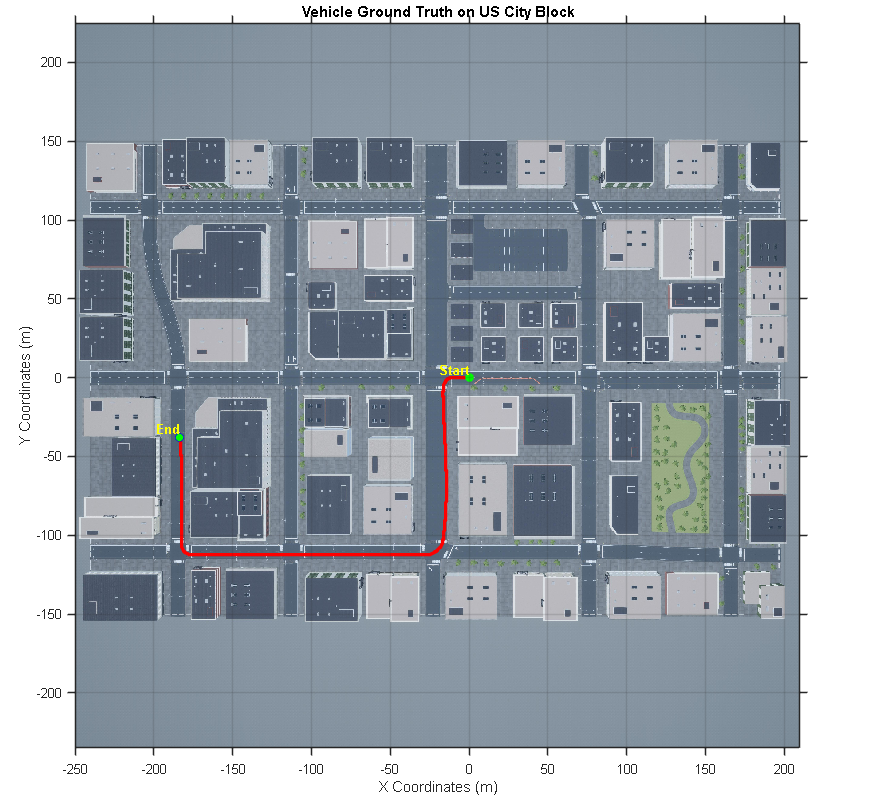

%Visualize the Ground Truth Position on US City Block Map
data = load('sim3d_SpatialReferences.mat');
spatialRef = data.spatialReference.USCityBlock;

figure;
fileName = 'sim3d_USCityBlock.jpg';
imshow(fileName,spatialRef);
set(gca,'YDir','normal')
xlabel('X Coordinates (m)')
ylabel('Y Coordinates (m)')

%Plot the position data
hold on;
plot(refX, refY, 'ro', 'MarkerSize', 2, 'MarkerFaceColor', 'r');

plot(refX(1), refY(1), 'go', 'MarkerSize', 6, 'MarkerFaceColor', 'g'); % Start point
text(refX(1), refY(1), 'Start', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'y');

plot(refX(end), refY(end), 'bo', 'MarkerSize', 6, 'MarkerFaceColor', 'g'); % End point
text(refX(end), refY(end), 'End', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'y');


title('Vehicle Ground Truth on US City Block');
grid on;

## **IMU Localization Model**

Adding noise to the Ground Truth data to simulate the noisy data output from the actual IMU sensor (Hardware) because IMU simulation block sensor lacks bias noise which leads to unrealistic results. 

IMU sensor contains accelerometers which provides linear acceleration in three axes, gyroscopes which provides angular velocity in three axes, and magnetometers. So, these data after performing double integration of the IMU accelerometer data to get the position and single integration for gyroscope data to get orientation. Then, we add noise to simulate real hardware.

***IMU/INS Localization Workflow:***

- Reshape Pose Vehicle data in the pose Data vector NX3.

- Specify the IMU Noise specifications of velocity and Acceleration according to the IMU model used.

- Then generate the noise for each sample.

- Adding noise to the actual data.

- Finally, calculate the error in position and orientation. 

***It's not an accurate way to simulate the IMU noisy data because the randn function generates different random numbers every iterations which affects on the reading, so it will be beneficial to edit the IMU simulink block to simulate error and generate more realistic data***

%Differentiating ground-truth data before applying noise to simulate IMU generated data.
IMUVx = diff(refX) / Ts;
IMUAx = diff(IMUVx) / Ts;

IMUVy = diff(refY) / Ts;
IMUAy = diff(IMUVy) / Ts;

IMUVyaw = diff(refYaw) / Ts;

%IMU noise specifications for linear acceleration and angular velocity
Acc_accuracy = 0.035; %Meters/s^2
angVel_accuracy = 2; %Degrees/sec

%Generate noise
Acc_noise = Acc_accuracy * randn(numFrames-2, 1); %Noise for linear acceleration
Vel_noise = angVel_accuracy * randn(numFrames-1, 1); %Noise for angular velocity

%Add noise to the pose data
IMUAxn = [0; (IMUAx + Acc_noise); (IMUAx(end) + Acc_noise(end))];
IMUAyn = [0; (IMUAy + Acc_noise); (IMUAy(end) + Acc_noise(end))];
IMUWzn = [0; (IMUVyaw + Vel_noise)];

%Setting initial conditions for position and acceleration.
IMUVxBar = zeros(numFrames,1);
IMUVxBar(1) = IMUVx(1);
IMUVyBar = zeros(numFrames,1);
IMUVyBar(1) = IMUVy(1);
IMUX = zeros(numFrames,1);
IMUX(1)= refX(1);
IMUY = zeros(numFrames,1);
IMUY(1)= refY(1);
IMUYaw = zeros(numFrames,1);
IMUYaw(1)= refYaw(1);

%Assuming zero initial pose.
 for i = 2:(numFrames)
    %Using double integration to get position from acceleration and single step integration to get orientation from angular velocity
    IMUVxBar(i) = IMUVxBar(i-1) + (IMUAxn(i) * Ts); %Velociy from integration (X direction)
    IMUVyBar(i) = IMUVyBar(i-1) + (IMUAyn(i) * Ts); %Velociy from integration (Y direction)
    IMUX(i) = IMUX(i-1) + (IMUVxBar(i) * Ts) + (0.5 * (Ts^2) * IMUAxn(i)); %Position from  integration (X direction)
    IMUY(i) = IMUY(i-1) + (IMUVyBar(i) * Ts) + (0.5 * (Ts^2) * IMUAyn(i)); %Position from integration (Y direction)
    IMUYaw(i) = IMUYaw(i-1) + (IMUWzn(i) * Ts); %orientation from integration (Yaw angle)
 end  

Afterthat, We visualize the IMU sensor Pose output Vs. Ground truth and the IMU sensor Pose error in distance and orientation. 

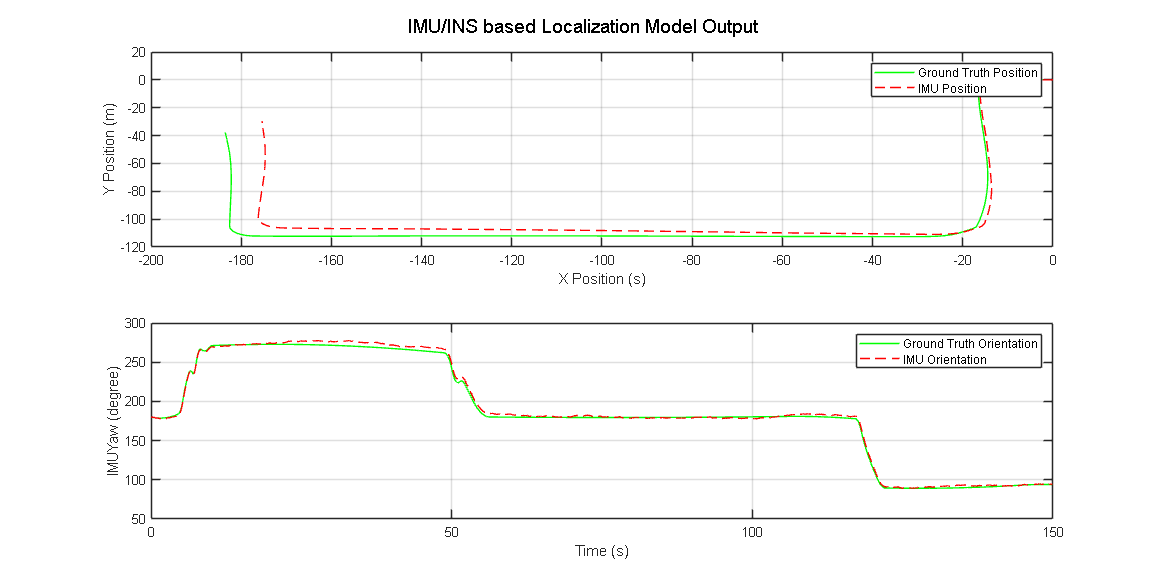

%Plot Ground Truth Pose vs. IMU/INS Estimated Pose
figure;
figure('Position', [50, 50, 2000, 1000]); % [left bottom width height]

subplot(2, 1, 1);
plot(refX, refY, 'g');
hold on;
plot(IMUX, IMUY, 'r--');
xlabel('X Position (s)');
ylabel('Y Position (m)');
legend('Ground Truth Position', 'IMU Position');
grid on;

subplot(2, 1, 2);
plot(timeVector, refYaw, 'g');
hold on;
plot(timeVector, IMUYaw, 'r--');
xlabel('Time (s)');

ylabel('IMUYaw (degree)');
legend('Ground Truth Orientation', 'IMU Orientation');
grid on;
sgtitle('IMU/INS based Localization Model Output');

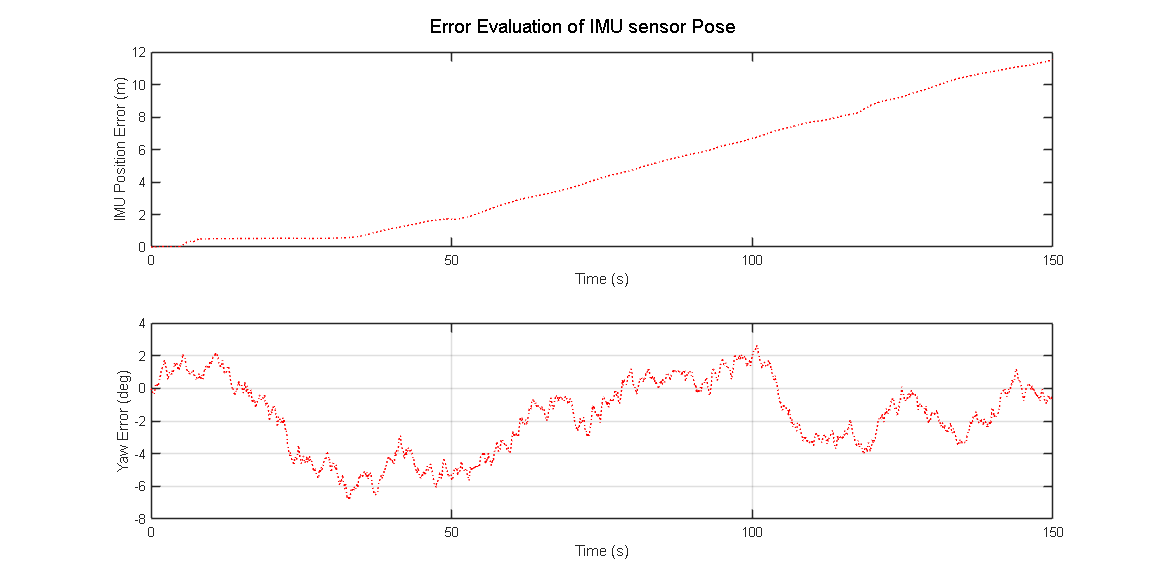

%Error in Pose of IMU sensor  
YawDiffIMU = refYaw - IMUYaw;
IMUError = zeros(numFrames, 1);

for i= 1:numFrames
    IMUError(i) = sqrt((refX(i) - IMUX(i))^2 + (refY(i) - IMUY(i))^2);
end

figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

subplot(2, 1, 1);
plot(timeVector, IMUError, 'r:');
xlabel('Time (s)');
ylabel('IMU Position Error (m)');

subplot(2, 1, 2);
plot(timeVector, YawDiffIMU, 'r:');
xlabel('Time (s)');

ylabel('Yaw Error (deg)');
grid on;

sgtitle('Error Evaluation of IMU sensor Pose');

## **GPS Localization Model** 

The next step to work with GPS data is Converting LLA Global Coordinates (received from GPS block) to ENU Local coordinates because the comparison with ground truth and other sensors are in local not global frame and making sure that the yaw angle is connected (no wrapping); for comparison reasons with other sensory data.

*Then visualizing the results of data obtained and error according to ground truth data.*

***GPS Localization Workflow: ***

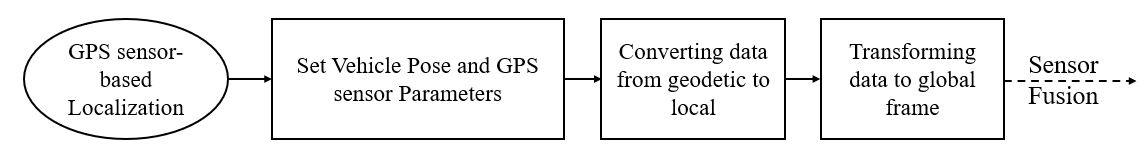

This Pseudocode describes the sequence of converting Geodetic LLA  Coordinates to ENU Coordinates in the for loop:

 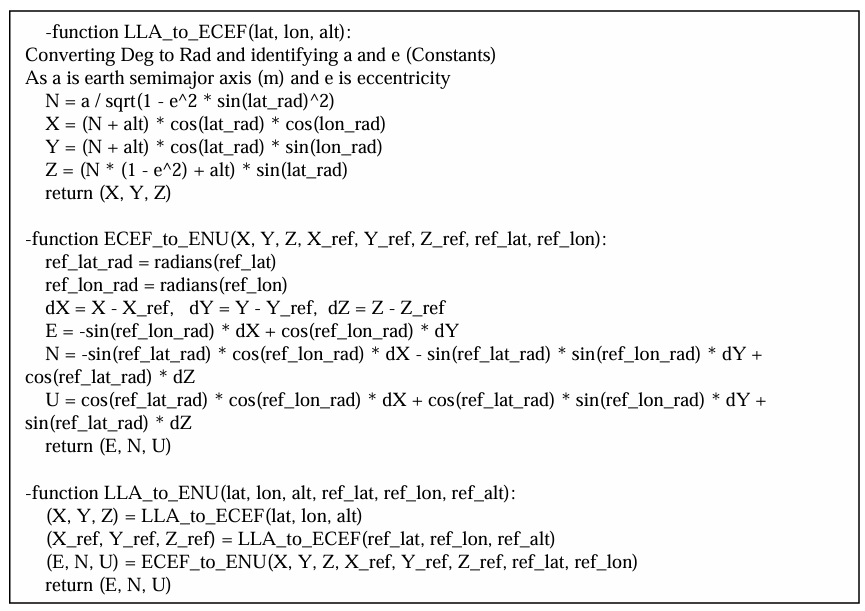

The next step in the loop is to convert angles to avoid discontinuity. 

GPSx = zeros(numFrames, 1);
GPSy = zeros(numFrames, 1);

%Reshape LLA GPS data 
GPSYaw = squeeze(Results.Course.Data);
LLA_data = squeeze(Results.LLA.Data);

%Convert course angles range from 0 to 360 to include all angles ranges
GPSYaw = rad2deg(unwrap(deg2rad(GPSYaw)));


for i = 1:numFrames
    %Convert LLA coordinates to ENU coordinates
    [deltaE, deltaN, ~] = lla_to_enu(LLA_data(1, 1), LLA_data(2, 1), LLA_data(3, 1), LLA_data(1, i), LLA_data(2, i), LLA_data(3, i));
    GPSx(i) = deltaE;
    GPSy(i) = deltaN;
end

In the next two steps, we visualize the GPS Estimated Pose wrt Ground Truth Pose and GPS error in position and orientation. 

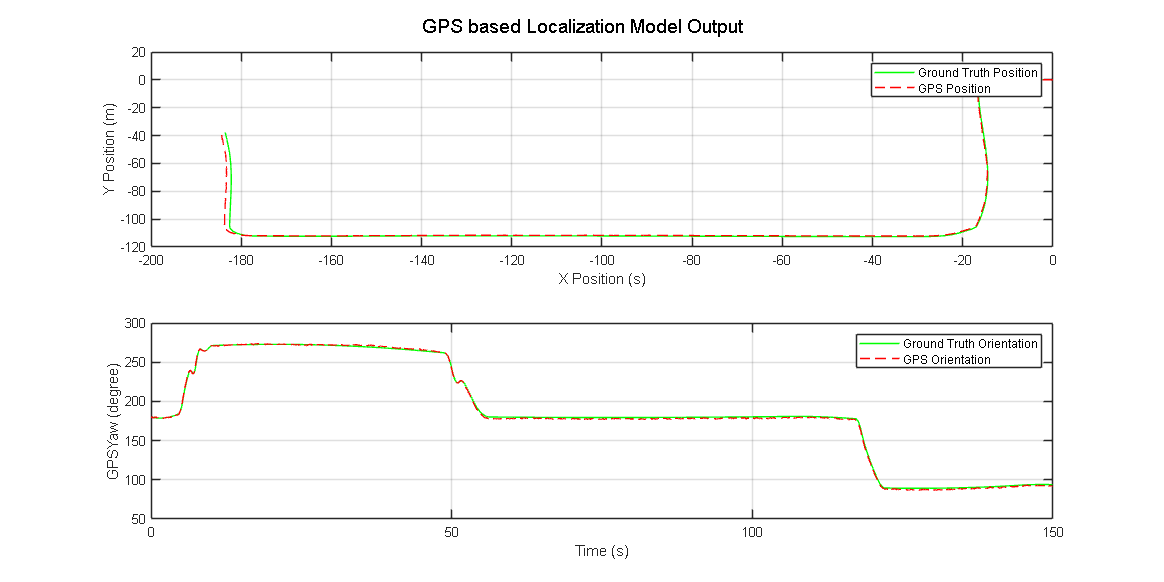

%Plot Ground Truth Pose vs. GPS Estimated Pose
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

subplot(2, 1, 1);
plot(refX, refY, 'g');
hold on;
plot(GPSx, GPSy, 'r--');
xlabel('X Position (s)');
ylabel('Y Position (m)');
legend('Ground Truth Position', 'GPS Position');
grid on;

subplot(2, 1, 2);
plot(timeVector, refYaw, 'g');
hold on;
plot(timeVector, GPSYaw, 'r--');
xlabel('Time (s)');

ylabel('GPSYaw (degree)');
legend('Ground Truth Orientation', 'GPS Orientation');
grid on;
sgtitle('GPS based Localization Model Output');

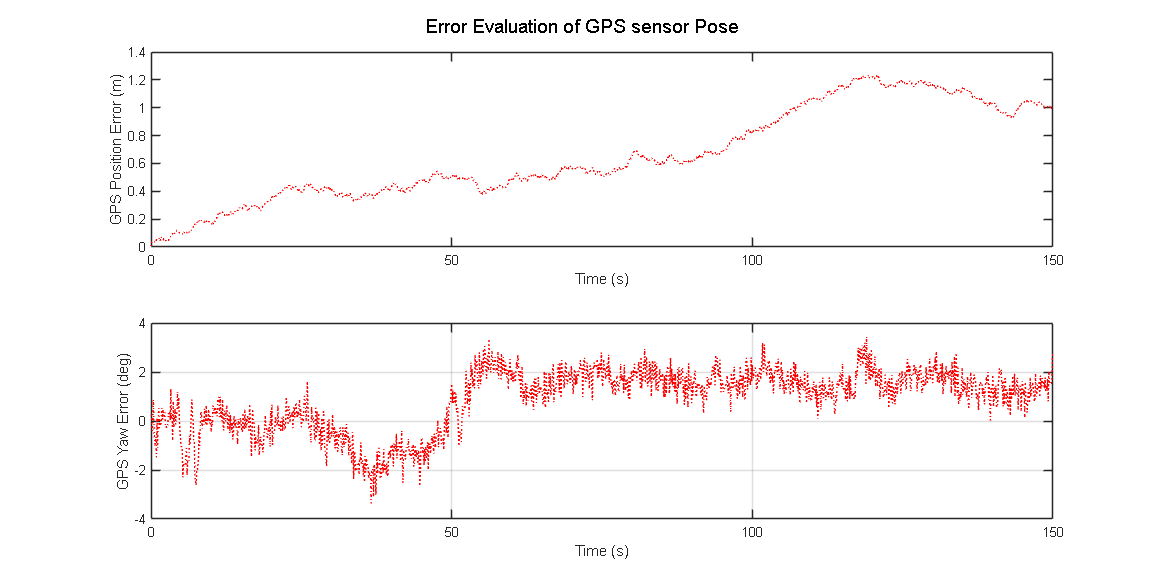

%Error in distance of GPS sensor  
YawDiffGPS = refYaw - GPSYaw;
GPSError = zeros(numFrames, 1);

for i= 1:numFrames
    GPSError(i) = sqrt((refX(i) - GPSx(i))^2 + (refY(i) - GPSy(i))^2);
end

%Graphing error
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

subplot(2, 1, 1);
plot(timeVector, GPSError, 'r:');
xlabel('Time (s)');
ylabel('GPS Position Error (m)');

subplot(2, 1, 2);
plot(timeVector, YawDiffGPS, 'r:');
xlabel('Time (s)');

ylabel('GPS Yaw Error (deg)');
grid on;

sgtitle('Error Evaluation of GPS sensor Pose');

## Mono-Camera Localization Model

***Camera Localization Workflow:***

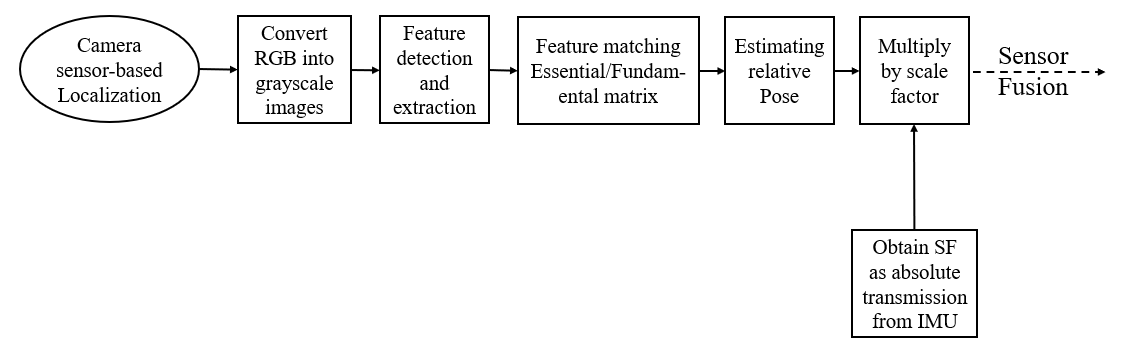

After converting images into grayscale ones, image features are used to find references in the environment. These features are detected and extracted using KAZE algorithms which detects features in high-contrast and textured areas. Feature matching is then performed with the help of inlier points to construct the Essential matrix.

The estimated relative pose is normalized, so it multiplied by a scale factor, which is obtained from the absolute translation provided by the GPS (or IMU) to denormalized. This denormalization process ensures accurate pose estimation by relating each frame to the previous one. 

***In future work to get the best camera pose estimation, calclate the scale factor wth a fuzzy logic weights for each sensor (LiDAR-GPS-IMU) according to its reading to use the more accurate scale factor in each iteration.***

### **Camera Setup**

This section for setting the camera Position Scale Factor and Intrinsics Camera Parameters.

Afterthat The Localization will done on the Mono-camera using KAZE Functions and Essential Matrix for Position and Orientation Estimation. 

In Case you want to apply the model on another simulation and you faced an error (There is not enough features), change the no. of features in detection and matching features. As the number features differes from simulation to another according to the smoothiness of the images and its features, also differes according to the camera position if it's for front or rear of the vehicle or for the vehicle sides. 

***It is possible to change features detection method (SIFT - KAZE - SURF - ORB ...) and number of detected features, and compare results but for this step we have choosen KAZE method.***

%Camera Scale Factor Calculations from GPS  
%Calculate the Euclidean distance between consecutive positions
SF = sqrt((diff(GPSx)).^2 + (diff(GPSy)).^2);

%Creating cameraParams intrinsics
focalLength = [fx fy];
principalPoint = [cx cy];
cameraParams = cameraIntrinsics(focalLength, principalPoint, imageSize);

### **Front Camera Localizarion (On the center of the Vehicle Roof)**

For the next steps, we will store the images in a vector then visualize the sequence of frames with adjusting pose time to be suitable with the visualization. 

***If the images are stored in another director, just change the name of the folder in jpgFilesF = dir(fullfile('changed folder name/', '*.images type')). Also, change this name in the ConvertVideoToFrames file to save the images in the new director. ***

%Store Front Camera frames in a vector
jpgFilesF = dir(fullfile('MonoCameraGray/', '*.jpg')); %Name of the folder is same as name of the created folder in ConvertVideoToFrames Function
grayVectorF = cell(1, numel(jpgFilesF));

%Store Front Camera Gray images in a vector
for i = 1:numel(jpgFilesF)
    %Construct the file path
    filePathF = fullfile('MonoCameraGray/', jpgFilesF(i).name); %Name of the folder is same as name of the created folder in ConvertVideoToFrames Function
    %Read and store the images
    grayVectorF{i} = imread(filePathF);
end

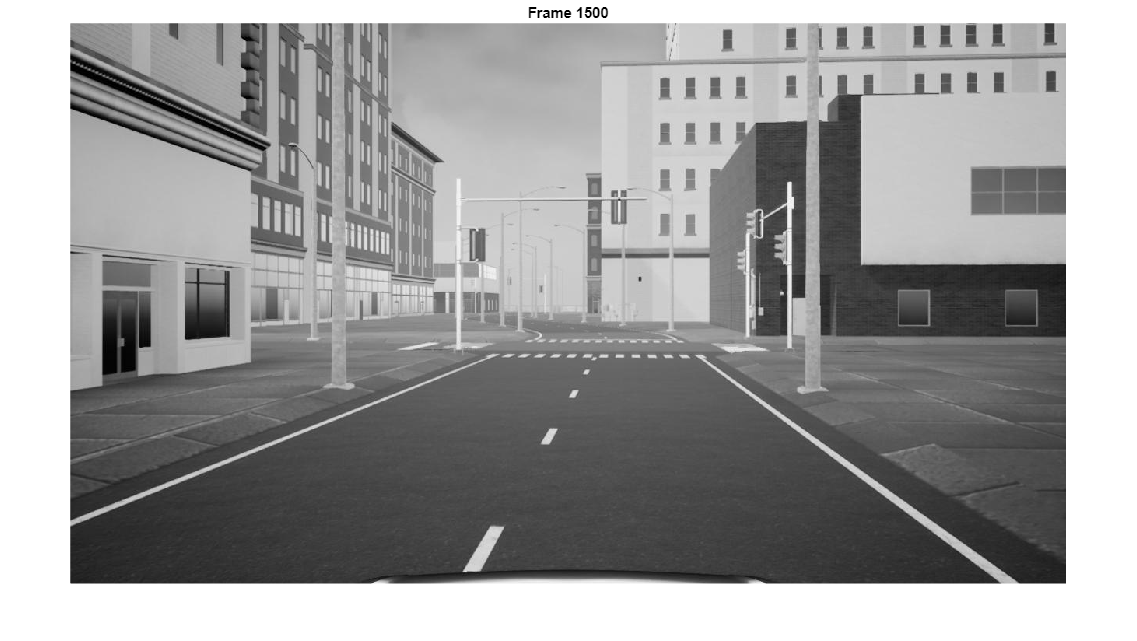

%Display the sequence of Front Camera Gray images
for i = 1:numel(grayVectorF)
    %Display the current image

    imshow(grayVectorF{i});
    title(['Frame ', num2str(i)]); %Adding frame number as a title
    pause(0.1); %Pausing the video according to recorded frame rate 
end

As mentioned in the camera localization workflow the main loop go through detecting and extracting features, then matching features with a help of inliers points afterthat applying essential and fundamental matrix to get relative pose and save it in a vectors camX, camY and cam Yaw with initialization to the camYaw from the initial IMU Yaw angle.     

camX(i+1) = camX(i) + t(3)*cos(deg2rad(IMUYaw(i)))*SF(i) - t(1)*cos((pi/2) - (deg2rad(IMUYaw(i))))*SF(i);

camY(Next) = camY(Before) + t(3)*sin(deg2rad(IMUYaw(i)))*SF(i) - t(1)*sin(pi/2 - (deg2rad(IMUYaw(i))))*SF(i);

where, 

t(3): transformation in the Z-axis --- depth in images.

t(1):  transformation in the X-axis --- to the right.

t(2): transformation in the Y-axis --- to Up. (ignore Y transformation because we assumed that the vehicle doesn't move up or down)

SF(i): scale factor vector from IMU. 

IMUYaw: Yaw angle from IMU.

%Loop for saving Front Camera estimated Pose
camX = zeros(numel(jpgFilesF), 1);
camY = zeros(numel(jpgFilesF), 1);
camYaw = zeros(numel(jpgFilesF), 1);
camYaw(1) = deg2rad(IMUYaw(1));

figure;
for i = 2:numel(grayVectorF)
        grayFrame1F = grayVectorF{i-1};
        grayFrame2F = grayVectorF{i};

        %Detect and match features for Position using SURF Function
        [matchedPoints1FEss, matchedPoints2FEss] = detectAndMatchFeatures(grayFrame1F, grayFrame2F, 'KAZE');

        %Estimate Essential matrix for Position (X & Y)
        [eMatrixF, inliersF, inlierPoints1FEss, inlierPoints2FEss] = estimateMatrix(matchedPoints1FEss, matchedPoints2FEss, cameraParams, 'Essential');

        %Estimate relative camera position
        [relPoseFEss, tFEss] = estimateRelativePose(eMatrixF, cameraParams, inlierPoints1FEss, inlierPoints2FEss);

        %Update yaw and position
        eulerAngles = rotm2eul(relPoseFEss.R, 'XYZ');
        camYaw(i) = camYaw(i-1) - eulerAngles(2);
        camX(i) = camX(i-1) + tFEss(3) * cos(deg2rad(IMUYaw(i))) * SF(i-1) - tFEss(1) * cos((pi/2) - (deg2rad(IMUYaw(i)))) * SF(i-1);
        camY(i) = camY(i-1) + tFEss(3) * sin(deg2rad(IMUYaw(i))) * SF(i-1) - tFEss(1) * sin((pi/2) - (deg2rad(IMUYaw(i)))) * SF(i-1);

        %Visualization of the matched features
        if (i == 2)
            fprintf('Out of 1500 Front Camera Frames, Processing the matching Frame No.: ');
        end

Out of 1500 Front Camera Frames, Processing the matching Frame No.: 

1500

        fprintf('\b\b\b\b\b%d', i);
        %Uncomment the next line to show the matched features
        %showMatchedFeatures(grayFrame1, grayFrame2, inlierPoints1FEss, inlierPoints2FEss, 'montage');
end

In the next two steps, we visualize the Camera Estimated Pose wrt Ground Truth Pose and Camera error in position and orientation. 

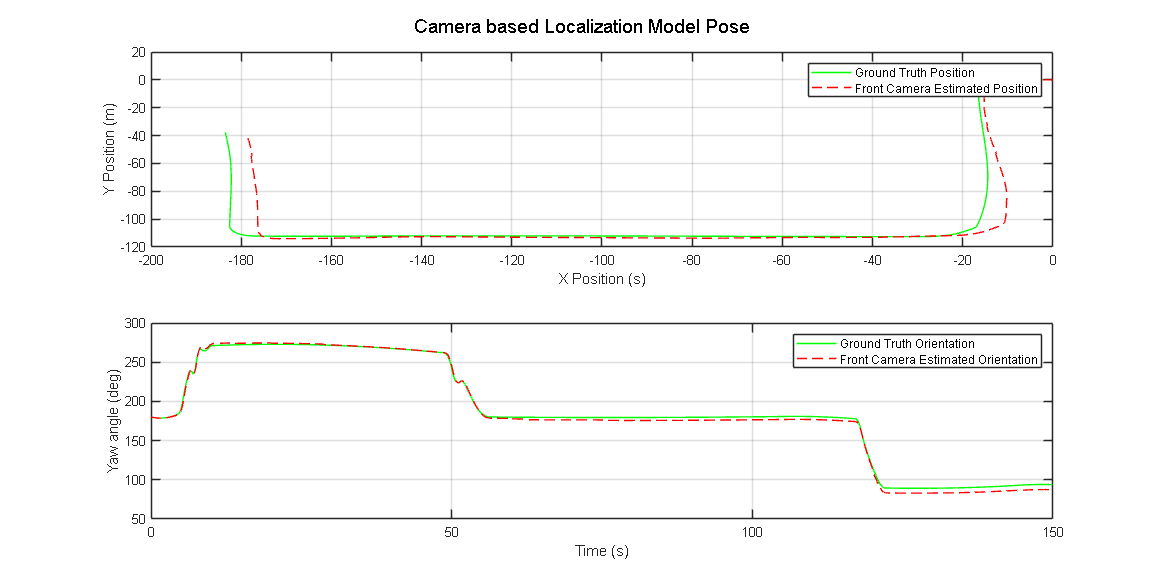

%Plot Ground Truth Pose vs. Front camera Estimated Pose
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

subplot(2, 1, 1);
plot(refX, refY, 'g');
hold on;
plot(camX, camY, 'r--');
xlabel('X Position (s)');
ylabel('Y Position (m)');
legend('Ground Truth Position', 'Front Camera Estimated Position');
grid on;

subplot(2, 1, 2);
plot(timeVector, refYaw, 'g');
hold on;
plot(timeVector, rad2deg(camYaw), 'r--');
xlabel('Time (s)');

ylabel('Yaw angle (deg)');
legend('Ground Truth Orientation', 'Front Camera Estimated Orientation');
grid on;
sgtitle('Camera based Localization Model Pose');

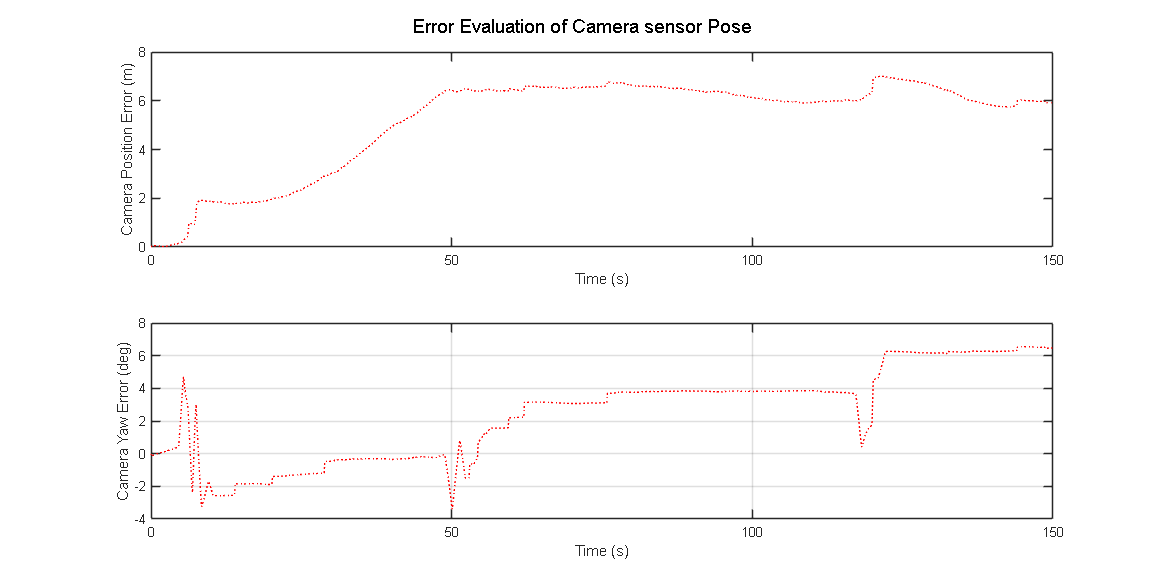

%Error in distance of Camera sensor  
YawDiffCam = refYaw - rad2deg(camYaw);
CameraError = zeros(numFrames, 1);

for i= 1:numFrames
    CameraError(i) = sqrt((refX(i) - camX(i))^2 + (refY(i) - camY(i))^2);
end

%Graphing error
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

subplot(2, 1, 1);
plot(timeVector, CameraError, 'r:');
xlabel('Time (s)');
ylabel('Camera Position Error (m)');

subplot(2, 1, 2);
plot(timeVector, YawDiffCam, 'r:');
xlabel('Time (s)');

ylabel('Camera Yaw Error (deg)');
grid on;

sgtitle('Error Evaluation of Camera sensor Pose');

## **Lidar Localization Model**

Here for Lidar-Based localization model, we use lidar data to be registered using certain metric (pointToPoint, pointToPlane, planeToPlane, etc..) to estimate relative pose between two consecutive frames in referencing the pcd data to local reference frame, we use lidar Yaw estimated as well as IMU referenced yaw angle as an integration between lidar and IMU data to perform a better Lidar-Based localization. 

Lets say that difference matching icp approaches or metric used follow the same steps as following: 

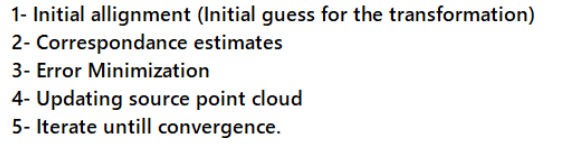

But to differentiate between approach and another, step 2 and 3 differ according to matching metric used. 

Then at the end of this section, results are graphed compared to Ground Truth data as well as difference between lidar-based approach and Ground Truth data with and without integrating with the angle from IMU module.

***LiDAR Localization Workflow:***

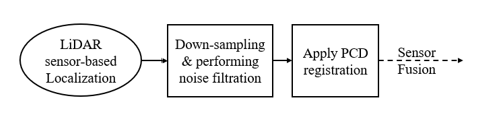

1. Organizing data 

2. Down sampling data 

3. Apply registration approache. 

***As yaw angle is embedded in the calculation for referencing the relative pose for the local frame, we use lidar angle as well as IMU angle in Lidar-INS referenced approach for estimating the pose as the INS according to different data processing provides more accurate angles.***

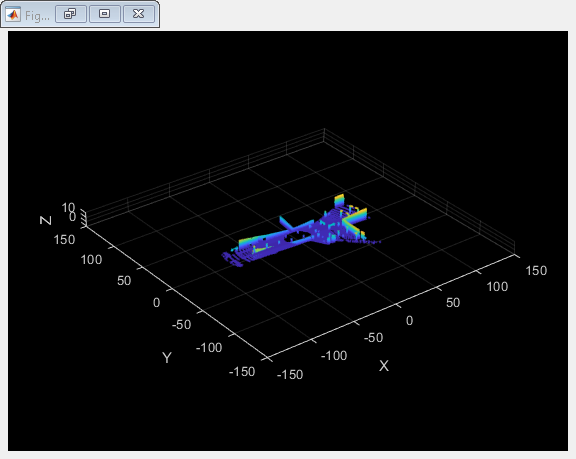

%Visualize point cloud data
xlimits = [-150 150];
ylimits = [-150 150];
zlimits = [ -5 10];
coder.extrinsic('isOpen', 'pcplayer')
player = pcplayer(xlimits, ylimits, zlimits);
pcdData = Results.ptCloudData1.signals.values;
pcdArray = reshape(pcdData, [(Vfov/Vres)*(Hfov/Hres), 3, size(pcdData,4)]);

for i = 1:size(pcdData,4)
    pcdX = pcdArray(:, 1,i);
    pcdY = pcdArray(:, 2,i);
    pcdZ = pcdArray(:, 3,i);
    point_cloud_data = [pcdX, pcdY, pcdZ];
    

    %Update the plot with the point cloud for the current frame
    view(player, point_cloud_data)
    %pause(0.1); % Adjust the pause duration as needed
end

To perform point cloud registration, pcd data are downsampled and filtered from any noise after stored in pointCloud objects to be passed to pcregistericp function. 

Downsampling using gridAverage method breaks down the boundary of pcd data into boxes with size = the number givent to pcdownsample function, then taking average data for points insidde each box to be representing the box with only one point. 

The figure below illustrates the process:

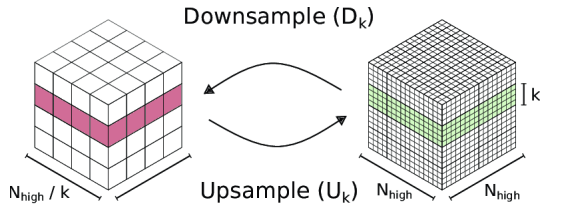

%Downsampling 
pointCloudObjects = cell(numFrames);
for i = 1:numFrames
 % Convert the array to a pointCloud object
 pointCloudObjects{i} = pointCloud(pcdArray(:,:,i));
 pointCloudObjects{i} = pcdownsample(pointCloudObjects{i}, 'gridAverage', 0.25);
end

***In Plane to Plane Approach: ***

1. Plane Extraction: Segment the point clouds into planar regions using methods  like RANSAC or region growing.  

2. Initial Alignment: Provide an initial guess of the transformation. 

3. Correspondence Estimation: Match corresponding planes between the source  and target clouds.  

4. Error Minimization: Minimize the distance between the corresponding planes,  which typically involves minimizing the angular and positional differences.  

5. Update: Apply the computed transformation.  

6. Iterate: Repeat steps 2-5 until convergence. 

***According to your results, you can change the approach (pointToPoint, pointToPlane, planeToPlane, etc..) and compare the results. ***

LidarX = zeros(1, numFrames);
LidarY = zeros(1, numFrames);
LidarYaw = zeros(1, numFrames);
LidarXBar = zeros(1, numFrames);
LidarYBar = zeros(1, numFrames);
transformations = zeros(4,4,numFrames);
transformations(:,:,1) = eye(4);

for i = 2:numFrames
    ptCloudOne = pointCloudObjects{i-1};
    ptCloudTwo = pointCloudObjects{i};
    [tform, ~, ~] = pcregistericp(ptCloudTwo, ptCloudOne, Metric="planeToPlane");
    
    %Extract rotation matrix and translation vector from transformation matrix
    R = tform.T(1:3, 1:3);
    eulerAngles = rotm2eul(R, 'XYZ');
    deltaYaw_vehicle_deg = -double(rad2deg(eulerAngles(3)));
    t = tform.T(4, 1:3)';
    
    deltaY_vehicle_m = (t(1) * sin(deg2rad(LidarYaw(i-1)+IMUYaw(1)))) - (t(2) * cos(deg2rad(LidarYaw(i-1)+IMUYaw(1)))); %Referencing to US city block Map coordinates
    deltaX_vehicle_m = - (t(2) * sin(deg2rad(LidarYaw(i-1)+IMUYaw(1)))) + (t(1) * cos(deg2rad(LidarYaw(i-1)+IMUYaw(1))));
    LidarX(i) = LidarX(i-1) + deltaX_vehicle_m;
    LidarY(i) = LidarY(i-1) + deltaY_vehicle_m;

    %for Lidar-IMU referenced
    deltaYBar_vehicle_m = (t(1) * sin(deg2rad(IMUYaw(i-1)))) - (t(2) * cos(deg2rad(IMUYaw(i-1)))); %Referencing to US city block Map coordinates
    deltaXBar_vehicle_m = - (t(2) * sin(deg2rad(IMUYaw(i-1)))) + (t(1) * cos(deg2rad(IMUYaw(i-1))));
    LidarXBar(i) = LidarXBar(i-1) + deltaXBar_vehicle_m;
    LidarYBar(i) = LidarYBar(i-1) + deltaYBar_vehicle_m;
    LidarYaw(i) = LidarYaw(i-1) + deltaYaw_vehicle_deg; 
    transformations(:,:,i-1) = (tform.A);
    
    %Display No. of Iterations
    if(i==2)

Out of 1500 Frames, Processing the matching Point Cloud No.: 

1500

        fprintf('Out of 1500 Frames, Processing the matching Point Cloud No.: ');
    end 
    fprintf('\b\b\b\b\b%d', i);
end

In the next two steps, we visualize the LiDAR Estimated Pose wrt Ground Truth Pose and LiDAR error in position and orientation. 

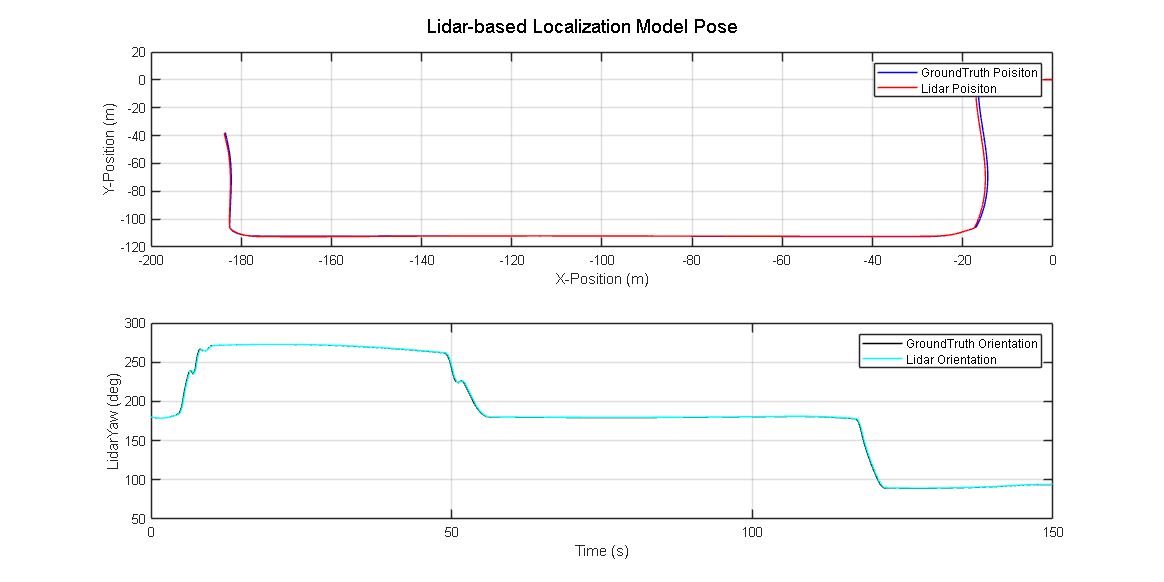

%Plot Ground Truth Pose vs. Lidar Estimated Pose
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

%Plot Position X & Y
subplot(2, 1, 1);
plot(refX, refY, 'b', LidarX, LidarY, 'r');
xlabel('X-Position (m)');
ylabel('Y-Position (m)');
legend('GroundTruth Poisiton', 'Lidar Poisiton');
grid on;

%Plot Orientation Yaw
subplot(2, 1, 2);
plot(timeVector, refYaw, 'k', timeVector, LidarYaw+IMUYaw(1), 'c');
xlabel('Time (s)');     

ylabel('LidarYaw (deg)');
legend('GroundTruth Orientation', 'Lidar Orientation');
grid on;
sgtitle('Lidar-based Localization Model Pose');

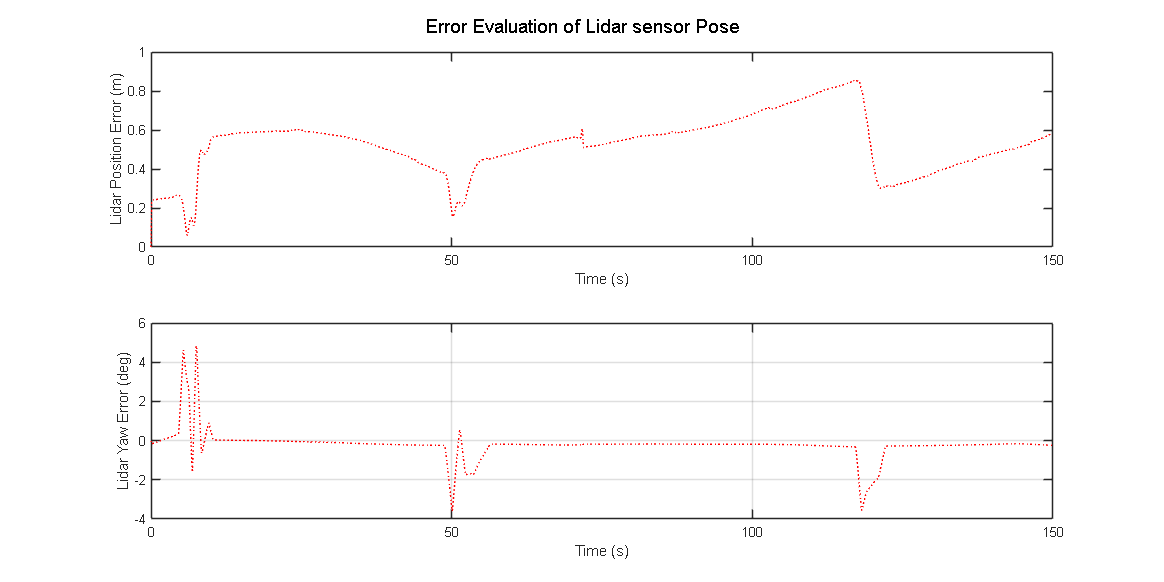

%Error in distance of Camera sensor  
LidardiffYaw = refYaw - (LidarYaw+refYaw(1))';
LidarError = zeros(numFrames, 1);

for i= 1:numFrames
    LidarError(i) = sqrt((refX(i) - LidarX(i)')^2 + (refY(i) - LidarY(i)')^2);
end

%Graphing error
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

subplot(2, 1, 1);
plot(timeVector, LidarError, 'r:');
xlabel('Time (s)');
ylabel('Lidar Position Error (m)');

subplot(2, 1, 2);
plot(timeVector, LidardiffYaw, 'r:');
xlabel('Time (s)');

ylabel('Lidar Yaw Error (deg)');
grid on;

sgtitle('Error Evaluation of Lidar sensor Pose');

### Point Cloud Map

Now we construct point cloud map from data obtained and with help of our lidar-based model utput to accumulate point cloud data per frame; to visualize the scene in form of point cloud map. Sequence of constructing point cloud map: 

- Read point cloud data per frame wrt sensor location.

- Transform data to map origin (Sensor location at the start of the data [Frame 0]).

when transforming point cloud data we extract points locations and convert them to homogenious to multiply them by transformation matrix [We stored before when performing icp registration] in order to transform them to the first frame before accumulation as described below.

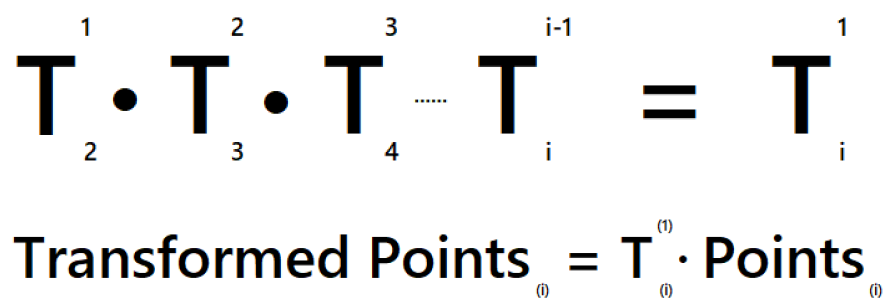

        3. Accumulate point cloud location into point cloud object to hold the point cloud map of the run.

You can adjust downsampling for processing power and time consuption and also to adjust the view of the point cloud map and how many points in it!

%Initializing an empty point cloud.
combinedPointCloud = pointCloud(pcdArray(:,:,1));
lidarYawDiff = cumsum(diff(LidarYaw));
transformationMatrix = eye(4);
%Looping through each frame and accumulate points.
for i = 2:numFrames
 currentFrame = pointCloud(pcdArray(:,:,i));
 %Extraction locations of points that are new to map only
 points = currentFrame.Location;
 %converting points to homogenious points
 homogeneousPoints = [points, ones(size(points, 1), 1)];
 transformationMatrix = transformationMatrix * transformations(:,:,i-1);

 %Applying transformation
 transformedPointsHomogeneous = (transformationMatrix * homogeneousPoints')';
 %Convering points back to cartesian for accumulation and converting back to point cloud object
 transformedPtCloud = pointCloud(transformedPointsHomogeneous(:, 1:3));
 %Accumulating current points to previous points
 combinedPointCloud = pcmerge(combinedPointCloud, transformedPtCloud, 0.1);
 %Merge with tolerance.

Out of 1500 Frames, Accumulating frame No.

1500

 if(i==2)
     fprintf('Out of 1500 Frames, Accumulating frame No.');
 end
 fprintf('\b\b\b\b\b%d', i);
end

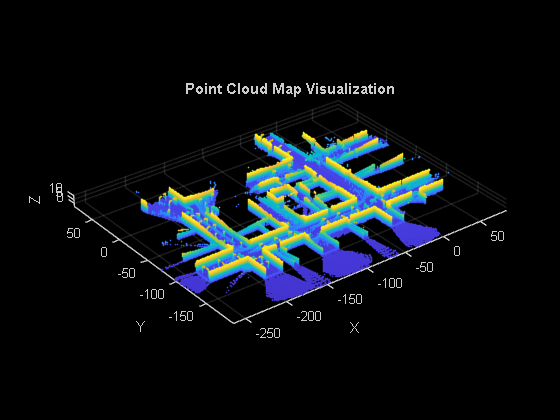

tMatrixInitial = eye(4);
%Assuming no initial drift in angles around X and Y axis
initialAngles = [deg2rad(refYaw(1)) 0 0]; %Angle in rad
tMatrixInitial (1:3,1:3) = eul2rotm(initialAngles);
%Assuming initial Z = 0
tMatrixInitial (1:3, 4) = [refX(1) refY(1) 0]';

%Extraction locations of points that are new to map only
points = combinedPointCloud.Location;
%converting points to homogenious points
pointsHomogeneous = [points, ones(size(points, 1), 1)];
%Applying transformation
transformedPointsHomogeneous = (tMatrixInitial * pointsHomogeneous')';
%Convering points back to cartesian for accumulation and converting back to point cloud object
transformedPoints = transformedPointsHomogeneous(:, 1:3);
transformedPointCloud = pointCloud(transformedPoints);

figure;
pcdMapX = transformedPointCloud.Location(:,1);
pcdMapY = transformedPointCloud.Location(:,2);
pcdMapZ = transformedPointCloud.Location(:,3);
point_cloud_map = [pcdMapX, pcdMapY, pcdMapZ];

pcshow(point_cloud_map)
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Point Cloud Map Visualization');

## Sensors-Based Localization Comparsion

In this step, we are comparing the performance of different sensors used for vehicle localization by analyzing their maximum position and orientation errors. For each sensor, we calculate the maximum absolute errors in position (in meters)  and orientation (in degrees). 

names = {'IMU', 'GPS', 'Camera', 'LiDAR'};

T = 4×3 table
     Sensors      Max Position Error (m)    Max Orientation Error (degree)
    __________    ______________________    ______________________________

    {'IMU'   }            11.521                        6.8381            
    {'GPS'   }            1.2349                        3.4494            
    {'Camera'}            7.0047                        6.5575            
    {'LiDAR' }           0.85443                        4.8468            


max_position_error = [max(abs(IMUError)), max(abs(GPSError)), max(abs(CameraError)), max(abs(LidarError))];
max_orientation_error = [max(abs(YawDiffIMU)), max(abs(YawDiffGPS)), max(abs(YawDiffCam)), max(abs(LidardiffYaw))];

%Create a sensor-based localization comparsion table 
T = table(names', max_position_error', max_orientation_error', 'VariableNames', {'Sensors', 'Max Position Error (m)', 'Max Orientation Error (degree)'})

## **Sensory Data Fusion**

### Standard Kalman Filter

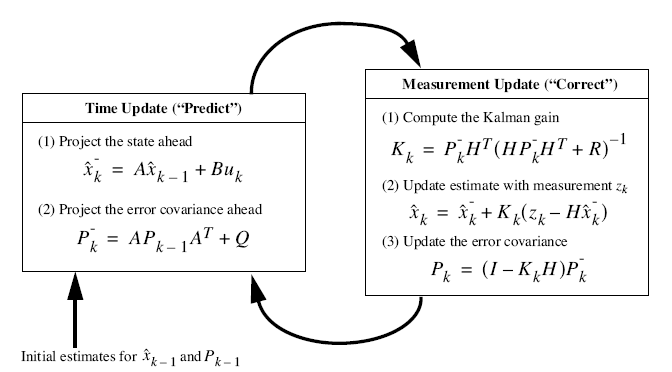

As  seen in previous figure, KF mainly consists of two phases, Prediction in which we used IMU data model  to predict vehicle state, but first of all we need to specify the filter states which are [X Y Vx Vy Yaw]'.

we have the readings of 4 sensors, so we use IMU/INS data in prediction phase  and the rest of the sensors (Camera, GPS, and LiDAR) in update phase. As data in prediction are ready from sensor-based step before in [X Y Yaw]' format, we use Measurement  matrix as follows: 

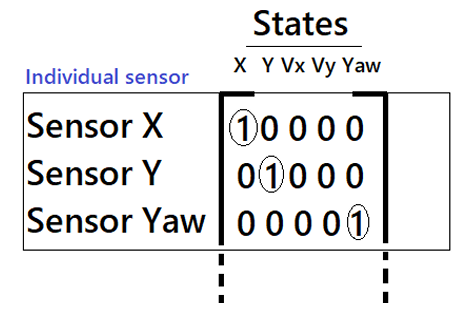

 Each sensor in order of Y (Input measurements to filter) will have three columns to map measurements to  states as described above, so in  KF we use H matrix with size 9x3. 

%Now with all data stored and set to be used in evaluating different filters estimates.
%Using Kalman Filter as follows (Initialzing Parameters and matrices (dt, F, G, H, Q, R) -> Setting Initial estimates -> Main Loop (Prediction -> update))

%1- Initialzing Parameters and Matrices 
dt = 0.1; %Time step for used synced data approximately.

%Initializing State Transition matrix (F)
F = [1, 0, dt, 0, 0;
     0, 1, 0, dt, 0;
     0, 0, 1, 0, 0;
     0, 0, 0, 1, 0;
     0, 0, 0, 0, 1];

%Initializing Control Matrix (G)
G = [(dt^2)/2, 0, 0;
     0, (dt^2)/2, 0;
     dt, 0, 0;
     0, dt, 0;
     0, 0, dt];

%Initializing Measurements matrix (H)
H = [1, 0, 0, 0, 0;
     0, 1, 0, 0, 0;
     0, 0, 0, 0, 1;
     1, 0, 0, 0, 0;
     0, 1, 0, 0, 0;
     0, 0, 0, 0, 1;
     1, 0, 0, 0, 0;
     0, 1, 0, 0, 0;
     0, 0, 0, 0, 1];

%Initializing Process noise covariance matrix (Q)
Q = diag([0.2, 0.2, 0.01, 0.01, 0.3].^2);

%Initializing Measurement noise covariance matrix (R) for every sensor
R = diag([0.4, 0.4, 0.3, 0.09, 0.09, 0.12, 0.128, 0.128, 0.125].^2); %CAMERA -> LIDAR -> GPS

%2-Setting initial estimates
%Initializing variables vector to hold xCheck, xHat, pCheck, pHat
xCheck = zeros(numFrames-1,5,1)';
pCheck = zeros(numFrames-1,5,5);
xHat = zeros(numFrames-1,5,1)'; % (+1) for inital estimates -> xHat(0)
pHat = zeros(numFrames-1,5,5); % (+1) for inital estimates -> pHat(0)
K = zeros(numFrames-1,5,9);

%Initializing state estimates xHat(k-1) -> first prediction iteration
xHat(:,1) = zeros(5,1); %[refX(0); refY(0); ve(0); vn(0); refYaw(0);]; -> are all assumed to be zero
xHat(5,1) = IMUYaw(1);

%Initializing error covariance estimates pHat(k-1) -> first prediction iteration
pHat(1,:,:) = eye(5);

%Input matrix
u = [IMUAxn IMUAyn IMUWzn]';

%Measurement Matrix y
y = [camX camY rad2deg(camYaw) LidarX' LidarY' (LidarYaw+IMUYaw(1))' GPSx GPSy GPSYaw]'; %to store input with size with size 9*numFrames

%3.0-Main filter loop
for i = 2:numFrames
    %Prediction step
    xCheck(:,i) = (F * xHat(:,i-1)) + (G * u(:,i-1)); %Replacing initial estimates with zeros to work with absolute difference readings
    pCheck(i,:,:) = (F * reshape(pHat(i-1,:,:),5, 5) * F') + Q;
    %Update step -> proceeed update step in 3 stages ->
    K(i,:,:) = (reshape(pCheck(i,:,:), 5, 5) * H') * (inv(((H *reshape(pCheck(i,:,:), 5, 5) * H') + R)));
    xHat(:,i) = xCheck(:,i) + reshape(K(i,:,:), 5, 9)*(y(:,i) - (H * xCheck(:,i)));
    pHat(i,:,:) = (eye(5) - (reshape(K(i,:,:), 5, 9) * H)) * reshape(pCheck(i,:,:),5, 5);
end

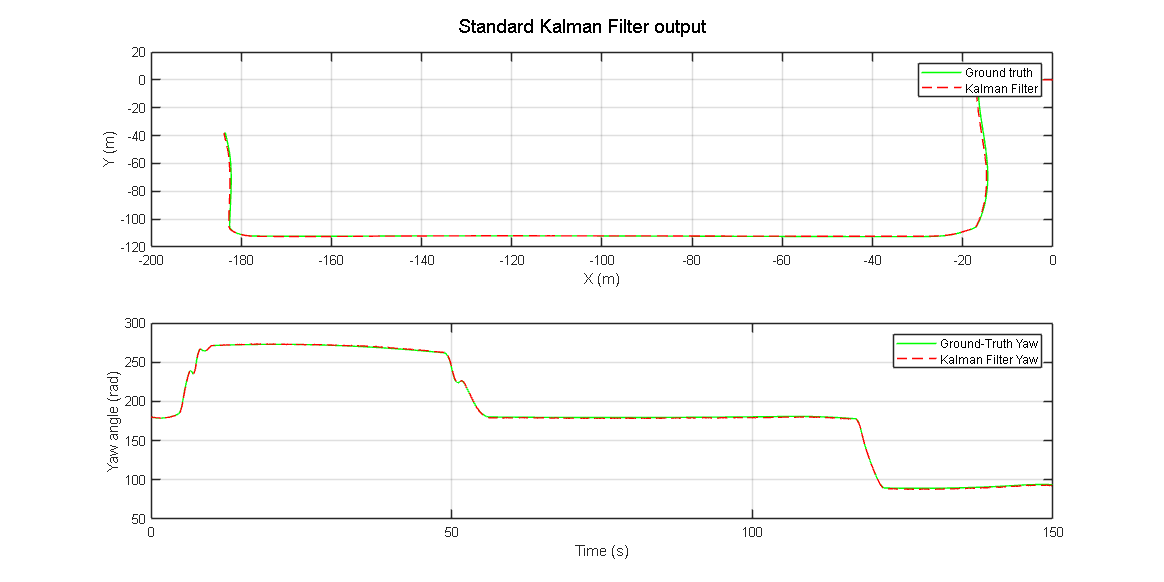

%Seperating 2D Pose from states for visualization
kfX = xHat(1, :);
kfY = xHat(2, :);
kfYaw = xHat(5, :);
%Graphing Filter output in comparison with GPS data as the ground truth
figure;
figure('Position', [50, 50, 2000, 1000]); % [left bottom width height]

subplot(2, 1, 1);
plot(refX, refY, 'g');
hold on;
plot(kfX, kfY, 'r--');
xlabel('X (m)');
ylabel('Y (m)');
legend('Ground truth', 'Kalman Filter');
grid on;

subplot(2, 1, 2);
plot(timeVector, refYaw, 'g');
hold on;
plot(timeVector, kfYaw, 'r--');

xlabel('Time (s)');
ylabel('Yaw angle (rad)');
legend('Ground-Truth Yaw', 'Kalman Filter Yaw');
grid on;
sgtitle('Standard Kalman Filter output');       

### Weighted Sum Estimation

For the second sensor fusion method we use similar formula for average model but adding weights to every sensor, these weights might be representative of sensor reading quality but here they are constant along the path.

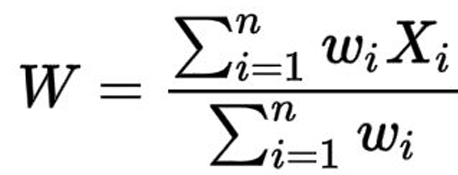

This formula will be used two times, firstly with considering GPS data in the filter, and secondly neglecting GPS data to see how the rest of the sensors will behave in predicting the vehicle states. Then the output of both methods are graphed to visualize the output.

#### Weighted Sum Estimation Including GPS

XGWs = zeros(numFrames, 1);
YGWs = zeros(numFrames, 1);
YawGWs = zeros(numFrames, 1);

XSenGWs = [camX, LidarX', GPSx, IMUX];
YSenGWs = [camY, LidarY', GPSy, IMUY]; 
YawSenGWs = [rad2deg(camYaw), (LidarYaw+IMUYaw(1))', GPSYaw, IMUYaw];

WeigthGXY = [8, 30, 24, 5]; %Camera -> Lidar -> GPS -> IMU
WeigthGYaw = [10, 24, 30, 8]; %Camera -> Lidar -> GPS -> IMU

%Loop for Weighted sum cal.
for i= 1:numFrames
    XGWs(i,:) = sum(WeigthGXY .* XSenGWs(i,:)) / sum(WeigthGXY);
    YGWs(i,:) = sum(WeigthGXY .* YSenGWs(i,:)) / sum(WeigthGXY);
    YawGWs(i,:) = sum(WeigthGYaw .* YawSenGWs(i,:)) / sum(WeigthGYaw);
end

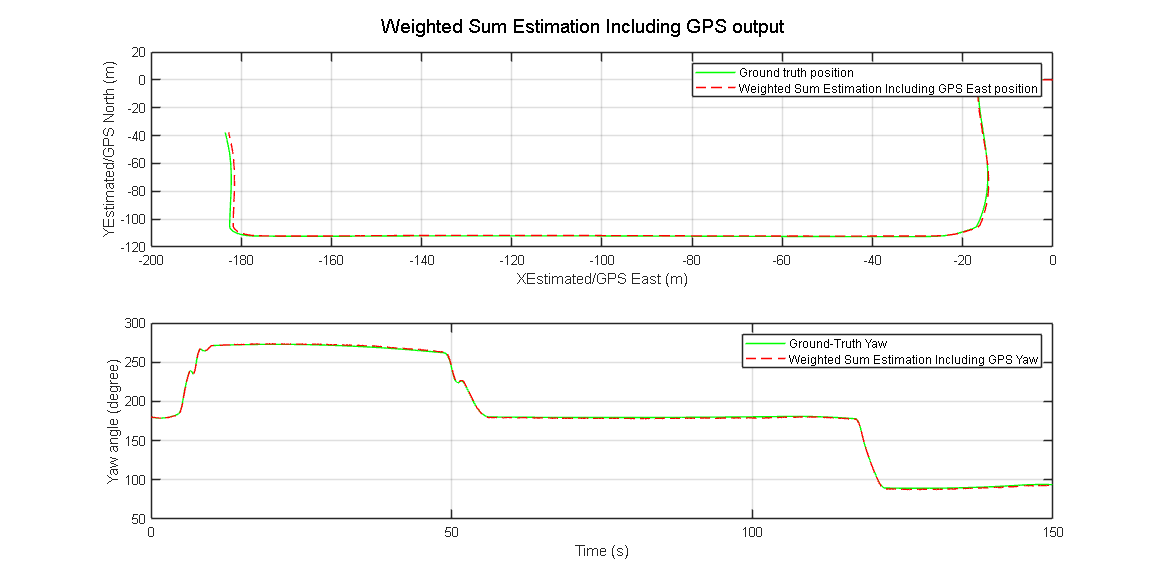

%Graphing Weighted Sum Estimation Including GPS output in comparison with GPS data as the ground truth
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

subplot(2, 1, 1);
plot(refX, refY, 'g');
hold on;
plot(XGWs, YGWs, 'r--');
xlabel('XEstimated/GPS East (m)');
ylabel('YEstimated/GPS North (m)');
legend('Ground truth position', 'Weighted Sum Estimation Including GPS East position');
grid on;

subplot(2, 1, 2);
plot(timeVector, refYaw, 'g');
hold on;
plot(timeVector, YawGWs, 'r--');

xlabel('Time (s)');
ylabel('Yaw angle (degree)');
legend('Ground-Truth Yaw', 'Weighted Sum Estimation Including GPS Yaw');
grid on;
sgtitle('Weighted Sum Estimation Including GPS output');

#### Weighted Sum Estimation Excluding GPS

XWs = zeros(numFrames, 1);
YWs = zeros(numFrames, 1);
YawWs = zeros(numFrames, 1);

WeigthXY = [10, 30, 0, 8]; %Camera -> Lidar -> GPS -> IMU
WeigthYaw = [10, 24, 0, 8]; %Camera -> Lidar -> GPS -> IMU

%Loop for Weighted sum cal.
for i= 1:numFrames
    XWs(i,:) = sum(WeigthXY .* XSenGWs(i,:)) / sum(WeigthXY);
    YWs(i,:) = sum(WeigthXY .* YSenGWs(i,:)) / sum(WeigthXY);
    YawWs(i,:) = sum(WeigthYaw .* YawSenGWs(i,:)) / sum(WeigthYaw);
end

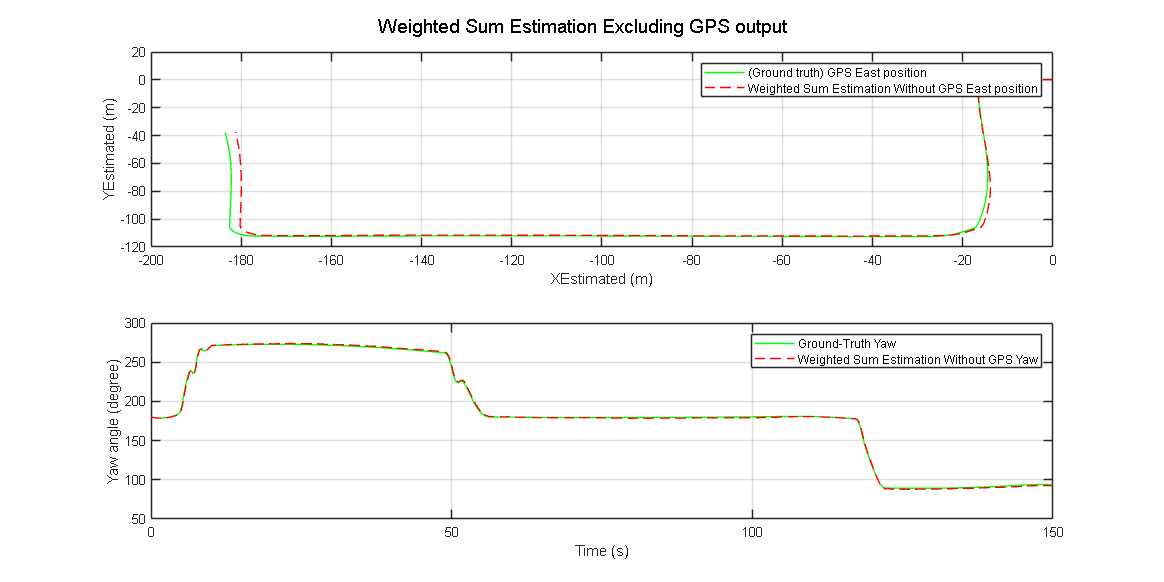

%Graphing Average Estimation output in comparison with GPS data as the ground truth
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

subplot(2, 1, 1);
plot(refX, refY, 'g');
hold on;
plot(XWs, YWs, 'r--');
xlabel('XEstimated (m)');
ylabel('YEstimated (m)');
legend('(Ground truth) GPS East position', 'Weighted Sum Estimation Without GPS East position');
grid on;

subplot(2, 1, 2);
plot(timeVector, refYaw, 'g');
hold on;
plot(timeVector, YawWs, 'r--');

xlabel('Time (s)');
ylabel('Yaw angle (degree)');
legend('Ground-Truth Yaw', 'Weighted Sum Estimation Without GPS Yaw');
grid on;
sgtitle('Weighted Sum Estimation Excluding GPS output');

### **Average Estimation Model**

The average estimation technique works by getting the average of  X-position, Y-position and Yaw-orientation for all sensors. Where, Xavg is average X,  Yavg is average Y, YAWavg is average Yaw from all sensors. 

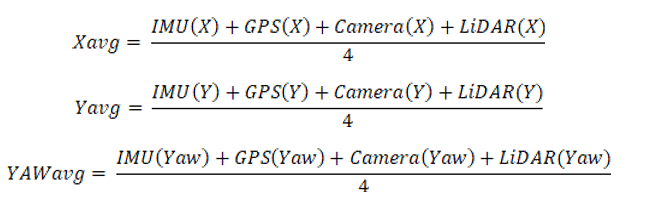

XAvg = zeros(numFrames, 1);
YAvg = zeros(numFrames, 1);
YawAvg = zeros(numFrames, 1);

for i= 1:numFrames
    XAvg(i) = (camX(i,:) + LidarX(:,i) + GPSx(i,:) + IMUX(i,:)) / 4;
    YAvg(i) = (camY(i,:) + LidarY(:,i) + GPSy(i,:) + IMUY(i,:)) / 4;
    YawAvg(i) = (rad2deg(camYaw(i,:)) + (LidarYaw(:,i)+refYaw(1))' + GPSYaw(i,:) + IMUYaw(i,:)) / 4;
end

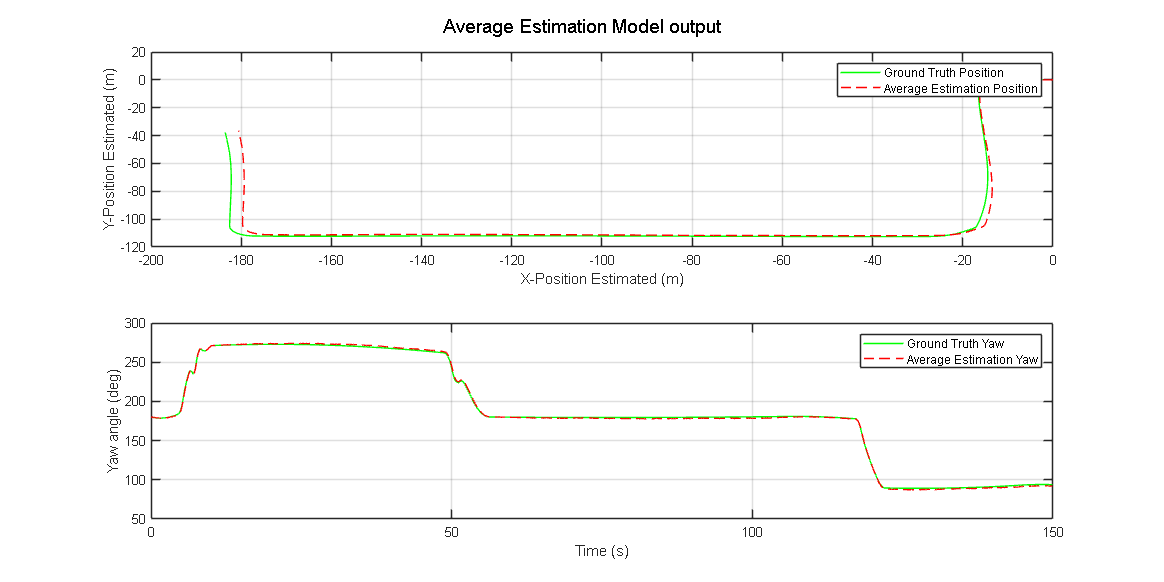

%Graphing Average Estimation output in comparison with GPS data as the ground truth
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

subplot(2, 1, 1);
plot(refX, refY, 'g');
hold on;
plot(XAvg, YAvg, 'r--');
xlabel('X-Position Estimated (m)');
ylabel('Y-Position Estimated (m)');
legend('Ground Truth Position', 'Average Estimation Position');
grid on;

subplot(2, 1, 2);
plot(timeVector, refYaw, 'g');
hold on;
plot(timeVector, YawAvg, 'r--');

xlabel('Time (s)');
ylabel('Yaw angle (deg)');
legend('Ground Truth Yaw', 'Average Estimation Yaw');
grid on;
sgtitle('Average Estimation Model output');

## **Sensor Fusion Comparsion**

In the following section, we visualize all the sensor routes with the ground truth route, then getting the max deviation in distance using Euclidean distance error to compare between all sensors and the max deviation in orientation (Yaw). 

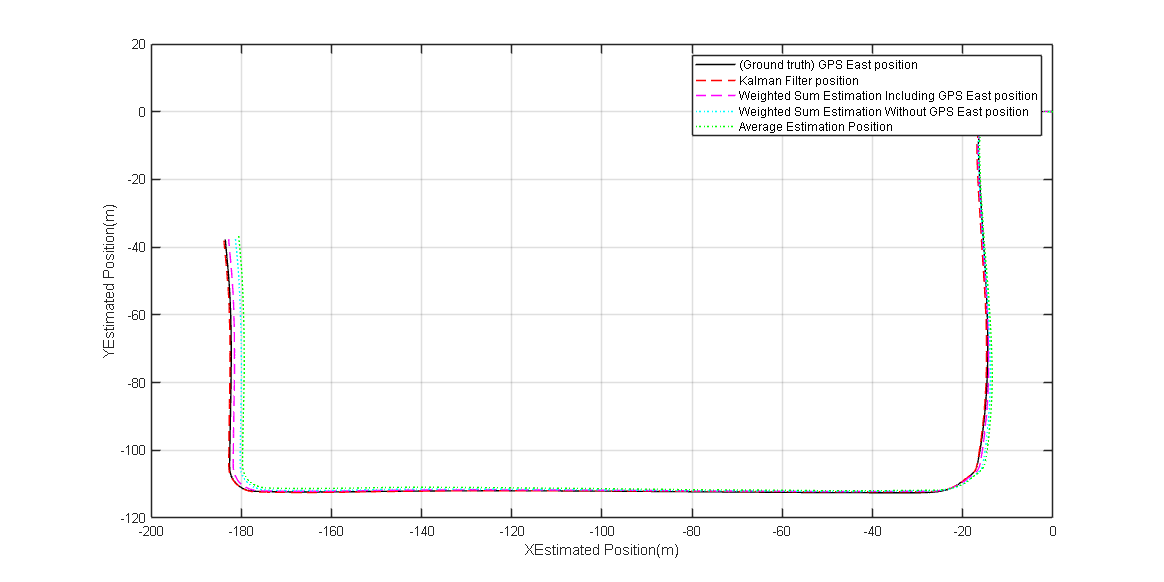

%Graph all Sensors Route 
figure;
figure('Position', [50, 50, 2000, 1000]); % [left bottom width height]

plot(refX, refY, 'black-');
hold on;
plot(kfX, kfY, 'r--');
plot(XGWs, YGWs, 'm--');
plot(XWs, YWs, 'c:');

plot(XAvg, YAvg, 'g:');
xlabel('XEstimated Position(m)');
ylabel('YEstimated Position(m)');
legend('(Ground truth) GPS East position', 'Kalman Filter position', 'Weighted Sum Estimation Including GPS East position', 'Weighted Sum Estimation Without GPS East position', 'Average Estimation Position');
grid on;

### Euclidean Distance Error Evaluation 

Euclidean distance is defined as the distance between two points. 

Euclidean distance formula is given by:

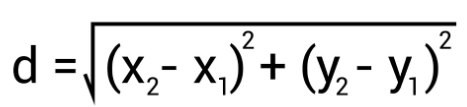

where: 

X2: Ground Truth (X)

X1: Estimated (X)

Y2: Ground Truth (Y)

Y1: Estimated (Y)

***Readings in Weighted Estimation techniqe higher than readings in LiDAR because Weighted Estimation and Average Weight Estimation aren't fusion techniques, but we used them only to show the data and error in different ways.***

%To obtain total distance of travel 
totalDist = 0;
dkf = zeros(numFrames, 1);
dGWs = zeros(numFrames, 1);
dWs = zeros(numFrames, 1);
dAvg = zeros(numFrames, 1);

for i= 2:numFrames
    deltaX = refX(i) - refX(i-1);
    deltaY = refY(i) - refY(i-1);
    dist = sqrt(deltaX^2 + deltaY^2);
    totalDist = totalDist + dist;
end
for i= 1:numFrames
    dkf(i)= sqrt((refX(i) - kfX(i))^2 + (refY(i) - kfY(i))^2);
    dGWs(i) = sqrt((refX(i) - XGWs(i))^2 + (refY(i) - YGWs(i))^2);
    dWs(i) = sqrt((refX(i) - XWs(i))^2 + (refY(i) - YWs(i))^2);
    dAvg(i) = sqrt(((refX(i) - XAvg(i))^2 + (refY(i) - YAvg(i))^2));
end
fusions = {'Average Estimates', 'Weighted Estimates Excluding GPS', 'GPS Weighted Estimates', 'KF Estimates'};

For a route with length = 359.407835 m

max_Position_deviation = [max(dAvg), max(dWs), max(dGWs), max(dkf)];
max_Orientation_deviation = [max(abs(refYaw-YawAvg)), max(abs(refYaw-YawWs)), max(abs(refYaw-YawGWs)), max(abs(refYaw-kfYaw'))];

FusionTable = 4×3 table
              Fusion Technique              Max Position Deviation (m)    Max Orientation Deviation (deg)
    ____________________________________    __________________________    _______________________________

    {'Average Estimates'               }              3.1995                          2.9606             
    {'Weighted Estimates Excluding GPS'}              2.6651                          4.1334             
    {'GPS Weighted Estimates'          }              1.2064                          2.0903             
    {'KF Estimates'                    }             0.55283                          1.8105             



%Displaying Average accuracy score per path
fprintf('For a route with length = %f m', totalDist);
%Create a table using the defined variables
FusionTable = table(fusions',max_Position_deviation', max_Orientation_deviation', 'VariableNames', {'Fusion Technique', 'Max Position Deviation (m)', 'Max Orientation Deviation (deg)'})

In the next final sections, First we graph error of usually high accuracy filter then low accuracy filters and finally graphing the best filter estimate (KF filter) on US city block Map with Ground Truth. 

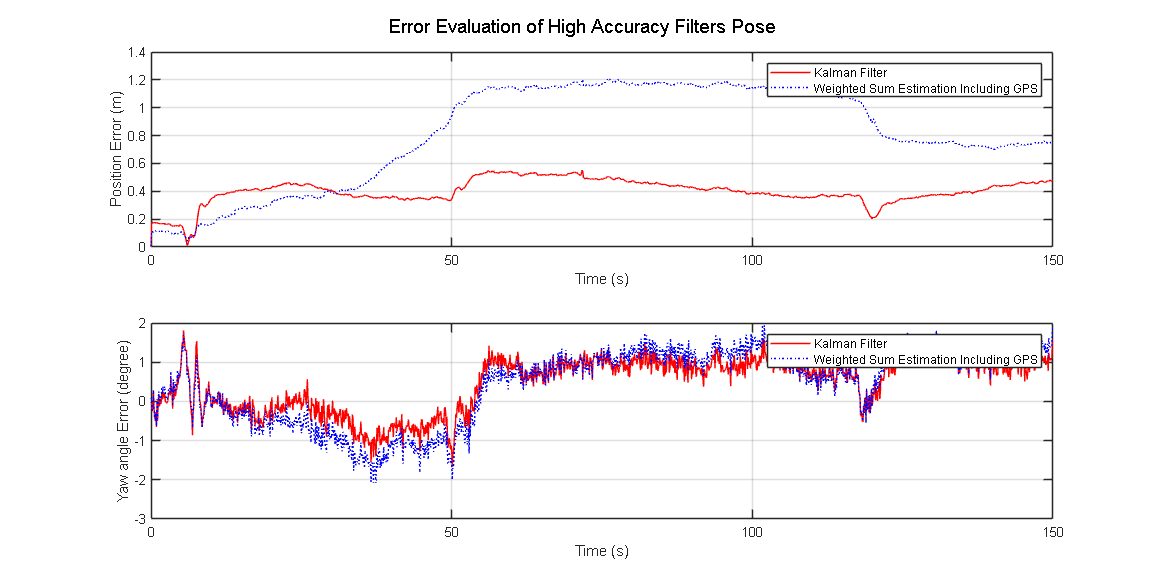

%Error Evaluation of Sensor Fusion Filters Pose
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

subplot(2, 1, 1);
plot(timeVector, dkf, '-r');
hold on;
plot(timeVector, dGWs, 'b:');
xlabel('Time (s)');
ylabel('Position Error (m)');
legend('Kalman Filter', 'Weighted Sum Estimation Including GPS');
grid on;

subplot(2, 1, 2);
plot(timeVector, (refYaw-kfYaw'), '-r');
hold on;
plot(timeVector, (refYaw-YawGWs), 'b:');
xlabel('Time (s)');

ylabel('Yaw angle Error (degree)');
legend('Kalman Filter', 'Weighted Sum Estimation Including GPS');
grid on;

sgtitle('Error Evaluation of High Accuracy Filters Pose');

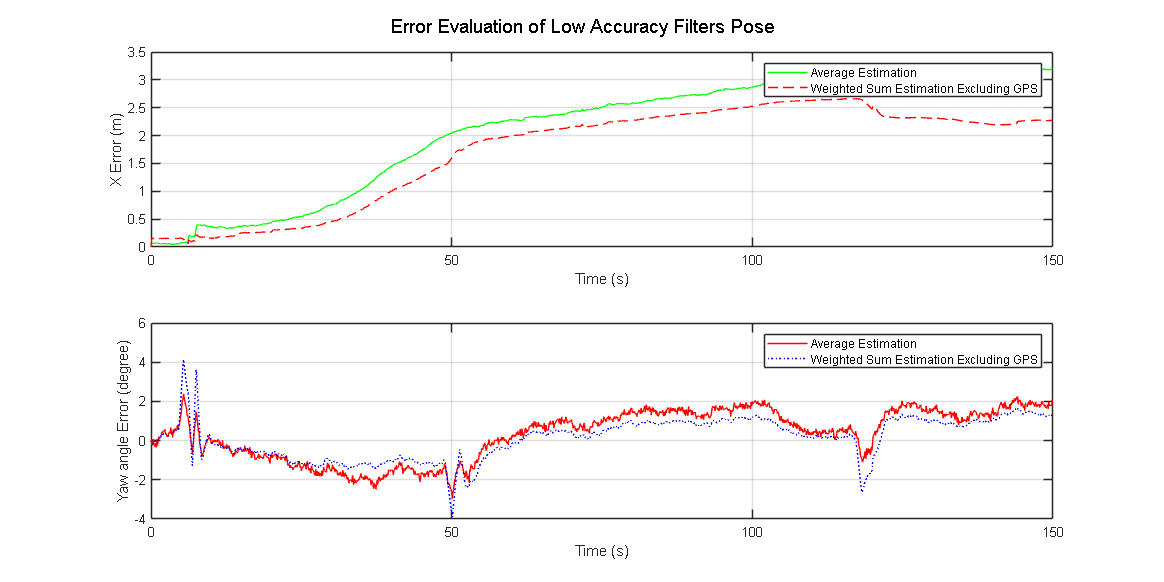

%Error Evaluation of Sensor Fusion Filters Pose
figure;
figure('Position', [50, 50, 2000, 1000]); %[left bottom width height]

subplot(2, 1, 1);
plot(timeVector, dAvg, 'g');
hold on;
plot(timeVector, dWs, 'r--');
xlabel('Time (s)');
ylabel('X Error (m)');
legend('Average Estimation', 'Weighted Sum Estimation Excluding GPS');
grid on;

subplot(2, 1, 2);
plot(timeVector, (refYaw-YawAvg), '-r');
hold on;
plot(timeVector, (refYaw-YawWs), 'b:');
xlabel('Time (s)');

ylabel('Yaw angle Error (degree)');
legend('Average Estimation', 'Weighted Sum Estimation Excluding GPS');
grid on;

sgtitle('Error Evaluation of Low Accuracy Filters Pose');

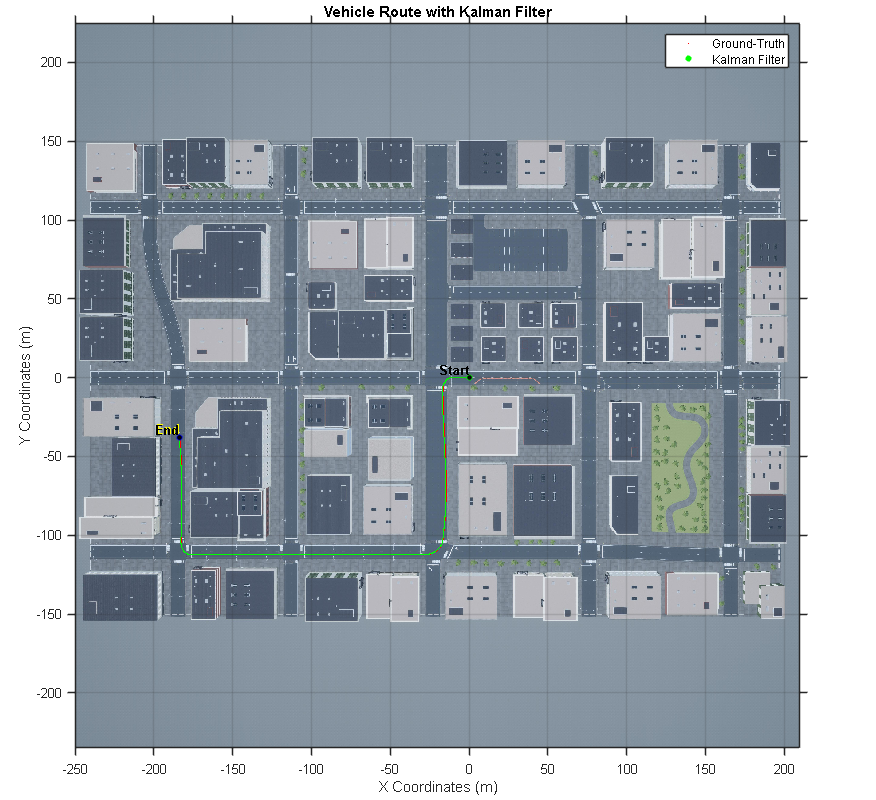

%Visualize the Position on US City Block Map
data = load('sim3d_SpatialReferences.mat');
spatialRef = data.spatialReference.USCityBlock;

figure;
fileName = 'sim3d_USCityBlock.jpg';
imshow(fileName,spatialRef);
set(gca,'YDir','normal')
xlabel('X Coordinates (m)')
ylabel('Y Coordinates (m)')

%Plot the position data
hold on;
plot(refX, refY, 'ro', 'MarkerSize', 0.5, 'MarkerFaceColor', 'r');
plot(refX(1), refY(1), 'go', 'MarkerSize', 4, 'MarkerFaceColor', 'g'); % Start point
text(refX(1), refY(1), 'Start', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'y');
plot(refX(end), refY(end), 'bo', 'MarkerSize', 4, 'MarkerFaceColor', 'g'); % End point
text(refX(end), refY(end), 'End', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'y');
hold on;
plot(kfX, kfY, 'go', 'MarkerSize', 0.5, 'MarkerFaceColor', 'black');
plot(kfX(1), kfY(1), 'go', 'MarkerSize', 4, 'MarkerFaceColor', 'black'); % Start point
text(kfX(1), kfY(1), 'Start', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'black');
plot(kfX(end), kfY(end), 'bo', 'MarkerSize', 4, 'MarkerFaceColor', 'black'); % End point

text(kfX(end), kfY(end), 'End', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'black');

legend('Ground-Truth', 'Kalman Filter');
title('Vehicle Route with Kalman Filter');
grid on;